## Problem 3 (Martin)


%%Transform matrix task -> base
syms x1 x2 x3 x4 x5 x6;
Ttask=[1 0 0 1.4; 0 1 0 0; 0 0 1 0.2; 0 0 0 1];

%via points matrices. T1 means T_p1^Task
T1=[0 x1 x2 0; 0 x3 x4 -0.5; -1 x5 x6 0; 0 0 0 1];
T2=[0 x1 x2 0.35; 0 x3 x4 0.5; -1 x5 x6 0; 0 0 0 1];
T3=[0 x1 x2 0.7; 0 x3 x4 -0.5; -1 x5 x6 0; 0 0 0 1];
T4=[0 x1 x2 1.05; 0 x3 x4 0.5; -1 x5 x6 0; 0 0 0 1];
T5=[0 x1 x2 1.4; 0 x3 x4 -0.5; -1 x5 x6 0; 0 0 0 1];

%if Q´s are changed, just rewrite equations in function Problem3.
%Q1
Ttrans1=Ttask*T1;
p_1=7/5; p_2=-0.5 ;p_3=1/5;x_1=0;x_2=0;x_3=-1;
[q1_trans1, q2_trans1, q3_trans1,q4_trans1] = problem3(x_1,x_3,p_1,p_2,p_3)

q1_trans1 = -0.3430

q2_trans1 = 1.7570

q3_trans1 = 1.5127

q4_trans1 = 2.9554

p_x1 = p_1;
p_y1 = p_2; %for problem4

%Q2
Ttrans2 = Ttask*T2;
p_1 = 7/4; p_2 = 0.5; p_3=1/5; x_1 = 0;x_2=0;x_3 = -1;  
[q1_trans2, q2_trans2, q3_trans2,q4_trans2] = problem3(x_1,x_3,p_1,p_2,p_3)

q1_trans2 = 0.2783

q2_trans2 = 1.7234

q3_trans2 = 1.8414

q4_trans2 = 2.9889

p_x2 = p_1;
p_y2 = p_2;

%Q3
Ttrans3 = Ttask*T3;
p_1=21/10; p_2 = -0.5; p_3=1/5; x_1=0;x_2=0;x_3 = -1;
[q1_trans3, q2_trans3, q3_trans3,q4_trans3] = problem3(x_1,x_3,p_1,p_2,p_3)

q1_trans3 = -0.2337

q2_trans3 = 1.6998

q3_trans3 = 2.1768

q4_trans3 = 3.0126

p_x3 = p_1;
p_y3 = p_2;

%Q4
Ttrans4 = Ttask*T4;
p_1=49/20; p_2=0.5; p_3=1/5; x_1=0;x_2=0;x_3 = -1;
[q1_trans4, q2_trans4, q3_trans4,q4_trans4] = problem3(x_1,x_3,p_1,p_2,p_3)

q1_trans4 = 0.2013

q2_trans4 = 1.6823

q3_trans4 = 2.5161

q4_trans4 = 3.0301

p_x4 = p_1;
p_y4 = p_2;

%Q5 = end-effector
Ttrans5 = Ttask*T5;
p_1=14/5; p_2 = -0.5; p_3= 1/5; x_1=0;x_2=0;x_3 = -1;
[q1_trans5, q2_trans5, q3_trans5,q4_trans5] = problem3(x_1,x_3,p_1,p_2,p_3)

q1_trans5 = -0.1767

q2_trans5 = 1.6689

q3_trans5 = 2.8580

q4_trans5 = 3.0435

p_x5 = p_1;
p_y5 = p_2;

## Problem 4 (Martin)

%%Problem 4 - use slides 25, lecture 6
%its transposed in the end. So I can get q3 of transformation2 by Q(2, 3)
Q = [q1_trans1 q2_trans1 q3_trans1 q4_trans1;q1_trans2 q2_trans2 q3_trans2 q4_trans2; q1_trans3 q2_trans3 q3_trans3 q4_trans3; q1_trans4 q2_trans4 q3_trans4 q4_trans4; q1_trans5 q2_trans5 q3_trans5 q4_trans5].'

Q =    -0.3430    0.2783   -0.2337    0.2013   -0.1767
    1.7570    1.7234    1.6998    1.6823    1.6689
    1.5127    1.8414    2.1768    2.5161    2.8580
    2.9554    2.9889    3.0126    3.0301    3.0435


%A = sym('a%d%d', [16 6]) %matrix to be filled with a coeffitients %TODO NUMBERING MUST BE SAME AS WITH ASSIGNMENT!!!
syms a15 a14 a13 a12 a11 a10 a25 a24 a23 a22 a21 a20 a35 a34 a33 a32 a31 a30 a45 a44 a43 a42 a41 a40 a55 a54 a53 a52 a51 a50 a65 a64 a63 a62 a61 a60 a75 a74 a73 a72 a71 a70 a85 a84 a83 a82 a81 a80 a95 a94 a93 a92 a91 a90 a105 a104 a103 a102 a101 a100 a115 a114 a113 a112 a111 a110 a125 a124 a123 a122 a121 a120 a135 a134 a133 a132 a131 a130 a145 a144 a143 a142 a141 a140 a155 a154 a153 a152 a151 a150 a165 a164 a163 a162 a161 a160
A = [a15, a14, a13, a12, a11, a10; a25, a24, a23, a22, a21, a20; a35, a34, a33, a32, a31, a30; a45, a44, a43, a42, a41, a40; a55, a54, a53, a52, a51, a50; a65, a64, a63, a62, a61, a60; a75, a74, a73, a72, a71, a70; a85, a84, a83, a82, a81, a80; a95, a94, a93, a92, a91, a90; a105, a104, a103, a102, a101, a100; a115, a114, a113, a112, a111, a110; a125, a124, a123, a122, a121, a120; a135, a134, a133, a132, a131, a130; a145, a144, a143, a142, a141, a140; a155, a154, a153, a152, a151, a150; a165, a164, a163, a162, a161, a160];

%Compute segment coeffitients  
%For example, segment1 will have Q_in (Trans1) Q(:, 1) Q_A=Q(:, 2):
for segment = 1:4
    A = problem4(A, segment, Q(:, segment), Q(:, segment+1));
end
A

A = round(A, 5); %display ROUNDING UP TO 3 DECIMAL, DONT USE vpa IS NEEDED ACCURATE!
A = fliplr(A) %discuss with joel

$$A = \left(\begin{array}{cccccc} 0.1165 & -0.58249 & 0.77665 & 0 & 0 & -0.34302\\ -0.00629 & 0.03143 & -0.0419 & 0 & 0 & 1.75696\\ 0.06163 & -0.30815 & 0.41087 & 0 & 0 & 1.51275\\ 0.00629 & -0.03143 & 0.0419 & 0 & 0 & 2.95543\\ -0.09601 & 0.48004 & -0.64005 & 0 & 0 & 0.2783\\ -0.00444 & 0.02218 & -0.02957 & 0 & 0 & 1.72344\\ 0.06288 & -0.31439 & 0.41918 & 0 & 0 & 1.84144\\ 0.00444 & -0.02218 & 0.02957 & 0 & 0 & 2.98895\\ 0.08157 & -0.40787 & 0.54383 & 0 & 0 & -0.23374\\ -0.00328 & 0.01638 & -0.02184 & 0 & 0 & 1.69978\\ 0.06363 & -0.31813 & 0.42418 & 0 & 0 & 2.17679\\ 0.00328 & -0.01638 & 0.02184 & 0 & 0 & 3.01261\\ -0.07088 & 0.3544 & -0.47253 & 0 & 0 & 0.20132\\ -0.00251 & 0.01255 & -0.01673 & 0 & 0 & 1.68231\\ 0.06411 & -0.32054 & 0.42739 & 0 & 0 & 2.51613\\ 0.00251 & -0.01255 & 0.01673 & 0 & 0 & 3.03008 \end{array}\right)$$

## Problem 5 (Martin)

%%Problem 5 - Do a Cartesian path planning
% In this problem, we dont need computed q values. Instead, we need
% coordinates of end-effector in the know points. Z coord is always the
% same, so we need only x, y. We have exactly that computed by "Ttrans"
% matrices and x, y coords are p_x=p1 and p_y=p2. Then, we will again compute
% Ttime*a=p_x for each segment
%A_c denotes matrix of unknowns for cartesian space
%A_c = sym('a%d%d', [8 6]) % For Problem 5: matrix to be filled with a coeffitients TODO NUMBERING MUST BE SAME AS WITH ASSIGNMENT!!!

P = [p_x1 p_y1;p_x2 p_y2;p_x3 p_y3;p_x4 p_y4;p_x5 p_y5].'

P =     1.4000    1.7500    2.1000    2.4500    2.8000
   -0.5000    0.5000   -0.5000    0.5000   -0.5000



syms a15 a14 a13 a12 a11 a10 a25 a24 a23 a22 a21 a20 a35 a34 a33 a32 a31 a30 a45 a44 a43 a42 a41 a40 a55 a54 a53 a52 a51 a50 a65 a64 a63 a62 a61 a60 a75 a74 a73 a72 a71 a70 a85 a84 a83 a82 a81 a80
A_c = [a15, a14, a13, a12, a11, a10; a25, a24, a23, a22, a21, a20; a35, a34, a33, a32, a31, a30; a45, a44, a43, a42, a41, a40; a55, a54, a53, a52, a51, a50; a65, a64, a63, a62, a61, a60; a75, a74, a73, a72, a71, a70; a85, a84, a83, a82, a81, a80];

for segment = 1:4
    A_c = problem5(A_c, segment, P(:, segment), P(:, segment+1));
end

P =     1.4000
         0
         0
    1.7500
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{15} & a_{14} & a_{13} & a_{12} & a_{11} & a_{10} \end{array}\right)$$

P =    -0.5000
         0
         0
    0.5000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{25} & a_{24} & a_{23} & a_{22} & a_{21} & a_{20} \end{array}\right)$$

P =     1.7500
         0
         0
    2.1000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{35} & a_{34} & a_{33} & a_{32} & a_{31} & a_{30} \end{array}\right)$$

P =     0.5000
         0
         0
   -0.5000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{45} & a_{44} & a_{43} & a_{42} & a_{41} & a_{40} \end{array}\right)$$

P =     2.1000
         0
         0
    2.4500
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{55} & a_{54} & a_{53} & a_{52} & a_{51} & a_{50} \end{array}\right)$$

P =    -0.5000
         0
         0
    0.5000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{65} & a_{64} & a_{63} & a_{62} & a_{61} & a_{60} \end{array}\right)$$

P =     2.4500
         0
         0
    2.8000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{75} & a_{74} & a_{73} & a_{72} & a_{71} & a_{70} \end{array}\right)$$

P =     0.5000
         0
         0
   -0.5000
         0
         0


$$ans = \left(\begin{array}{cccccc} a_{85} & a_{84} & a_{83} & a_{82} & a_{81} & a_{80} \end{array}\right)$$


A_c = round(A_c, 5); %display ROUNDING UP TO 3 DECIMAL, DONT USE if NEEDED ACCURATE!
A_c = fliplr(A_c)

$$A\_c = \left(\begin{array}{cccccc} 0.06563 & -0.32813 & 0.4375 & 0 & 0 & 1.4\\ 0.1875 & -0.9375 & 1.25 & 0 & 0 & -0.5\\ 0.06563 & -0.32813 & 0.4375 & 0 & 0 & 1.75\\ -0.1875 & 0.9375 & -1.25 & 0 & 0 & 0.5\\ 0.06563 & -0.32813 & 0.4375 & 0 & 0 & 2.1\\ 0.1875 & -0.9375 & 1.25 & 0 & 0 & -0.5\\ 0.06563 & -0.32813 & 0.4375 & 0 & 0 & 2.45\\ -0.1875 & 0.9375 & -1.25 & 0 & 0 & 0.5 \end{array}\right)$$

## Problem 6 - Compute Jacobian

syms q1 q2 q3 q4 a4;

a1=0;
alpha1=-(sym(pi)/2);
d1=1.5;
theta1=q1;

a2=0;
alpha2=sym(pi)/2;
d2=0;
theta2=q2;

a3=0;
alpha3=sym(pi)/2;
d3=q3;
theta3=sym(pi);

a4=a4;
alpha4=sym(pi)/2;
d4=0;
theta4=q4;

A1=[cos(theta1) -sin(theta1)*cos(alpha1) sin(theta1)*sin(alpha1) a1*cos(theta1); sin(theta1) cos(theta1)*cos(alpha1) -cos(theta1)*sin(alpha1) a1*sin(theta1); 0 sin(alpha1) cos(alpha1) d1; 0 0 0 1];
A2=[cos(theta2) -sin(theta2)*cos(alpha2) sin(theta2)*sin(alpha2) a2*cos(theta2); sin(theta2) cos(theta2)*cos(alpha2) -cos(theta2)*sin(alpha2) a2*sin(theta2); 0 sin(alpha2) cos(alpha2) d2; 0 0 0 1];
A3=[cos(theta3) -sin(theta3)*cos(alpha3) sin(theta3)*sin(alpha3) a3*cos(theta3); sin(theta3) cos(theta3)*cos(alpha3) -cos(theta3)*sin(alpha3) a3*sin(theta3); 0 sin(alpha3) cos(alpha3) d3; 0 0 0 1];
A4=[cos(theta4) -sin(theta4)*cos(alpha4) sin(theta4)*sin(alpha4) a4*cos(theta4); sin(theta4) cos(theta4)*cos(alpha4) -cos(theta4)*sin(alpha4) a4*sin(theta4); 0 sin(alpha4) cos(alpha4) d4; 0 0 0 1];

%Problem 6 - 
% See slide 6, lecture 6.
% A Jacobian column for our RRPR manipulator will be on the form
% [Zi-1;0] for a prismatic joint and [Zi-1*(0n-0(i-1));Zi-1] for a revolute
% joint
%Finding the transform from baseframe to Link 2 and 3 since we already have
%from base to Link 4
T01 = simplify(A1);
T02 = simplify(A1*A2);
T03 = simplify(A1*A2*A3);
T04 = simplify(A1*A2*A3*A4);

z0 = [0;0;1];
z1 = T01(1:3,3);
z2 = T02(1:3,3);
z3 = T03(1:3,3);
z4 = T04(1:3,3);

o0 = [0;0;0];
o1 = T01(1:3,4)

$$o1 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{2} \end{array}\right)$$

o2 = T02(1:3,4)

$$o2 = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{2} \end{array}\right)$$

o3 = T03(1:3,4)

$$o3 = \left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{2}\right)+\frac{3}{2} \end{array}\right)$$

o4 = T04(1:3,4)

$$o4 = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ a_{4}\,\sin\left(q_{2}+q_{4}\right)+q_{3}\,\cos\left(q_{2}\right)+\frac{3}{2} \end{array}\right)$$


Jacobian = simplify([cross(z0,(o4-o0)) cross(z1,(o4-o1)) z2 cross(z3, (o4-o3)); z0 z1 [0;0;0] z3])

$$Jacobian = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sigma_{2} & \cos\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{4}\,\sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right)\,\sigma_{2} & \sin\left(q_{1}\right)\,\sigma_{1} & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & a_{4}\,\sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{2} & \cos\left(q_{2}\right) & \sigma_{3}\\ 0 & -\sin\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\sin\left(q_{2}+q_{4}\right)+q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{2}=\sigma_{3}-q_{3}\,\sin\left(q_{2}\right)\\ \sigma_{3}=a_{4}\,\cos\left(q_{2}+q_{4}\right) \end{array}$$

%J = [(sin(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, cos(q1)*((51*sin(q2 + q4))/50 + q3*cos(q2)), cos(q1)*sin(q2), (51*sin(q2 + q4)*cos(q1))/50; -(cos(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, sin(q1)*((51*sin(q2 + q4))/50 + q3*cos(q2)), sin(q1)*sin(q2), (51*sin(q2 + q4)*sin(q1))/50; sym(0), (cos(q1)^2*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + (sin(q1)^2*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, cos(q2), cos(q1)*((cos(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + q3*cos(q1)*sin(q2)) + sin(q1)*((sin(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + q3*sin(q1)*sin(q2)); sym(0), -sin(q1), sym(0), -sin(q1); sym(0), cos(q1), sym(0), cos(q1); sym(1), sym(0), sym(0), sym(0)]


## Problem 6 (Lukas) - Check singularities

q1_ = problem6_A(A,1)

q1_ =    -0.3430   -0.3430   -0.3430   -0.3430   -0.3430   -0.3429   -0.3429   -0.3428   -0.3426   -0.3425   -0.3423   -0.3421   -0.3418   -0.3415   -0.3411   -0.3407   -0.3402   -0.3396   -0.3390   -0.3384   -0.3376   -0.3368   -0.3360   -0.3350   -0.3340   -0.3329   -0.3317   -0.3305   -0.3292   -0.3277   -0.3263   -0.3247   -0.3230   -0.3213   -0.3194   -0.3175   -0.3155   -0.3134   -0.3112   -0.3089   -0.3066   -0.3041   -0.3015   -0.2989   -0.2962   -0.2933   -0.2904   -0.2874   -0.2843   -0.2811


q2_ = problem6_A(A,2)

q2_ =     1.7570    1.7570    1.7570    1.7570    1.7570    1.7570    1.7570    1.7569    1.7569    1.7569    1.7569    1.7569    1.7569    1.7569    1.7569    1.7568    1.7568    1.7568    1.7567    1.7567    1.7567    1.7566    1.7566    1.7565    1.7565    1.7564    1.7564    1.7563    1.7562    1.7561    1.7561    1.7560    1.7559    1.7558    1.7557    1.7556    1.7555    1.7554    1.7552    1.7551    1.7550    1.7549    1.7547    1.7546    1.7544    1.7543    1.7541    1.7540    1.7538    1.7536


q3_ = problem6_A(A,3)

q3_ =     1.5128    1.5128    1.5128    1.5128    1.5128    1.5128    1.5128    1.5129    1.5130    1.5130    1.5131    1.5133    1.5134    1.5136    1.5138    1.5140    1.5143    1.5145    1.5149    1.5152    1.5156    1.5160    1.5165    1.5170    1.5175    1.5181    1.5187    1.5194    1.5201    1.5208    1.5216    1.5225    1.5233    1.5243    1.5252    1.5262    1.5273    1.5284    1.5296    1.5308    1.5320    1.5333    1.5347    1.5361    1.5375    1.5390    1.5406    1.5422    1.5438    1.5455


q4_ = problem6_A(A,4)

q4_ =     2.9554    2.9554    2.9554    2.9554    2.9554    2.9554    2.9554    2.9554    2.9555    2.9555    2.9555    2.9555    2.9555    2.9555    2.9555    2.9556    2.9556    2.9556    2.9556    2.9557    2.9557    2.9558    2.9558    2.9559    2.9559    2.9560    2.9560    2.9561    2.9562    2.9563    2.9563    2.9564    2.9565    2.9566    2.9567    2.9568    2.9569    2.9570    2.9571    2.9573    2.9574    2.9575    2.9577    2.9578    2.9580    2.9581    2.9583    2.9584    2.9586    2.9588


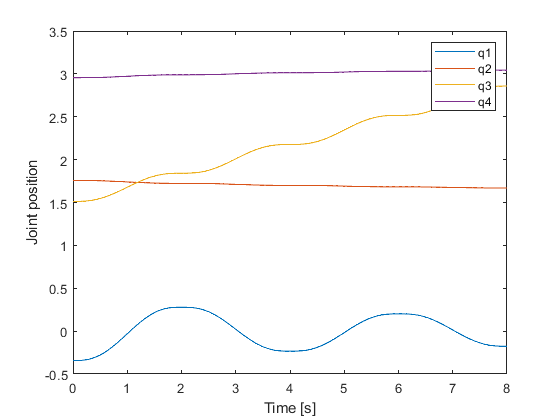


t = linspace(0,8,800);
plot(t,q1_), hold on
plot(t,q2_), hold on
plot(t,q3_), hold on
plot(t,q4_)
legend('q1','q2','q3','q4')
xlabel('Time [s]') 
ylabel('Joint position')


% Uncomment for rank calculation
% q1_ = interp1(t,q1_,linspace(0,8,10000000),'spline');
% q2_ = interp1(t,q2_,linspace(0,8,10000000),'spline');
% q3_ = interp1(t,q3_,linspace(0,8,10000000),'spline');
% q4_ = interp1(t,q4_,linspace(0,8,10000000),'spline');

% Jacobian copied from problem 6
min_J = 6;
for i=1:80
    q1 = q1_(i);
    q2 = q2_(i);
    q3 = q3_(i);
    q4 = q4_(i);
    J = [(sin(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, cos(q1)*((51*sin(q2 + q4))/50 + q3*cos(q2)), cos(q1)*sin(q2), (51*sin(q2 + q4)*cos(q1))/50; -(cos(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, sin(q1)*((51*sin(q2 + q4))/50 + q3*cos(q2)), sin(q1)*sin(q2), (51*sin(q2 + q4)*sin(q1))/50; sym(0), (cos(q1)^2*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + (sin(q1)^2*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50, cos(q2), cos(q1)*((cos(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + q3*cos(q1)*sin(q2)) + sin(q1)*((sin(q1)*(51*cos(q2 + q4) - 50*q3*sin(q2)))/50 + q3*sin(q1)*sin(q2)); sym(0), -sin(q1), sym(0), -sin(q1); sym(0), cos(q1), sym(0), cos(q1); sym(1), sym(0), sym(0), sym(0)];
    if rank(J)<min_J
        min_J = rank(J);
    end
end
min_J

min_J = 4

## Functions

**Problem 3 function (Martin)**

function [q1,q2,q3,q4] = problem3(x1,x3,p1,p2,p3)
    q1 = atan2(p2, p1);
    q2 = atan2((p1-(51/50)*x1)/cos(q1), p3-3/2-(51/50)*x3);
    q3 = (p3-(51/50)*x3-3/2)/cos(q2);
    q4 = atan2(x3, -x1/cos(q1)) - q2 +2*pi;
end

**Problem 4 function (Martin)**

function [A] = problem4(A, segment, Q_in, Q_A)
    Time_matrix = [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 2 0 0 0; 1 2 4 8 16 32; 0 1 4 12 32 80; 0 0 2 12 48 160];
    % we need to solve Ax=B -> x = A\B. In our case its Time_matrix*a=Q ->
    % -> a=Time_matrix\Q
    % Q = right side of equation = [Q_in;v_in;a_in;Q_A;v_A;a_A] but
    % velocity -> acceleration is zero
    
    for col = 1:4
        Q = [Q_in(col); 0; 0; Q_A(col); 0; 0];
        A(segment*4-4+col,:) = Time_matrix \ Q;
    end
end

**Problem 5 function (Martin)**

function [A_c] = problem5(A_c, segment, P_in, P_A)
    Time_matrix = [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 2 0 0 0; 1 2 4 8 16 32; 0 1 4 12 32 80; 0 0 2 12 48 160];

    for col = 1:2
        P = [P_in(col); 0; 0; P_A(col); 0; 0]
        A_c(segment*2-2+col,:)
        A_c(segment*2-2+col,:) = Time_matrix \ P;
    end
end


**Problem 6 function  (Lukas)**

function [q] = problem6_A(A,q_index)
    % q_index = 1 2 3 or 4
    q = [];
    for i = 0:3
        eq = A(4*i+q_index,:);
        for t = linspace(0,2,200)
            q(end+1) = sum([t^5 t^4 t^3 t^2 t 1].*eq);
        end
    end
end
